# ELEX7620 Lab 5

Name:  Ryan Wong, A00958475, and set:T

Objective:  to implement a MA filter with M = 4; in other words a moving average filter over 5 samples

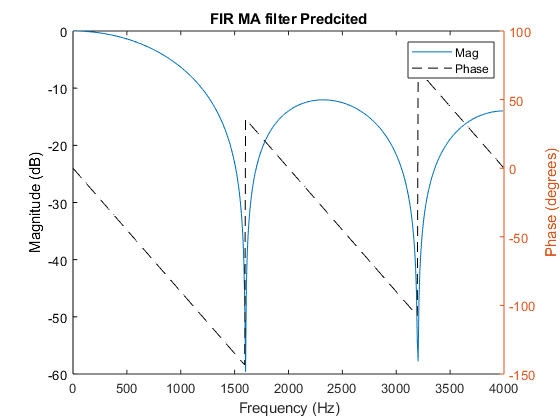

M = 4;                  %filter size
b = ones(1, M+1)/(M+1); %numerator coefficients
[h, f] = freqz(b, 1,512,8000);

freq = f;
mag = 20*log10(abs(h(:,:)));
phase = angle(h(:,:)) * 57.2958; 

figure(1)
clf
plot(freq,mag)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('FIR MA filter Predcited')
hold on
yyaxis right
plot(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## 3dB and Null locations

Nulls (Hz): 1602, 3203

3dB (Hz): 720

## Measurements

## Measurements

Record your measured data here and compare it against the theoretical results

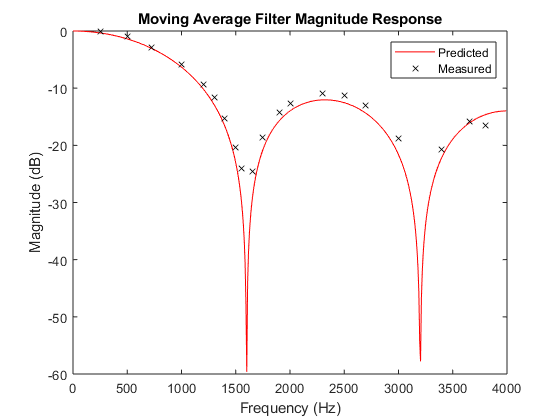

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[250, 1]
            [500, 0.904]
            [720, 0.736]
            [1000, 0.524]
            [1200, 0.348]
            [1300, 0.268]
            [1400, 0.176]
            [1500, 0.098]
            [1550, 00.064]
            [1650, 0.060]
            [1750, 0.12]
            [1900, 0.196]
            [2000, 0.236]
            [2500, 0.276]
            [2300, 0.288]
            [2700, 0.228]
            [3000, 0.116]
            [3400, 0.0930]
            [3650, 0.166]
            [3800, 0.153] 
           ];

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 1.02;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);


figure(2)
clf
plot(freq,mag,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Moving Average Filter Magnitude Response')
legend('Predicted', 'Measured')